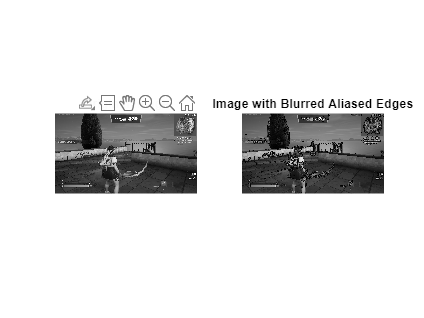

% Read the input image
inputImage = imread('AliasedImage.png'); % Replace 'input_image.jpg' with the path to your image
inputImage = rgb2gray(inputImage); % Convert to grayscale if necessary

% Apply Sobel edge detection to find edges
edgeImage = edge(inputImage, 'sobel');

% Create a mask to identify the aliased edges
aliasedEdges = edgeImage & ~bwareaopen(edgeImage, 100);

% Define Gaussian filter parameters
sigma = 2; % Standard deviation
kernelSize = 6*sigma + 1; % Choose an appropriate kernel size

% Create a Gaussian filter kernel
gaussianKernel = fspecial('gaussian', kernelSize, sigma);

% Blur the aliased edges
blurredEdges = conv2(double(aliasedEdges), gaussianKernel, 'same');

% Normalize the blurred image
blurredEdges = uint8((blurredEdges - min(blurredEdges(:))) / (max(blurredEdges(:)) - min(blurredEdges(:))) * 255);

% Combine the blurred edges with the original image
outputImage = inputImage;
outputImage(blurredEdges > 0) = blurredEdges(blurredEdges > 0);

% Display the original and processed images
figure;
subplot(1, 2, 1);
imshow(inputImage);
title('Original Image');
subplot(1, 2, 2);
imshow(outputImage);
title('Image with Blurred Aliased Edges');